# Numerical Calculus

-----

## The coffee bean model

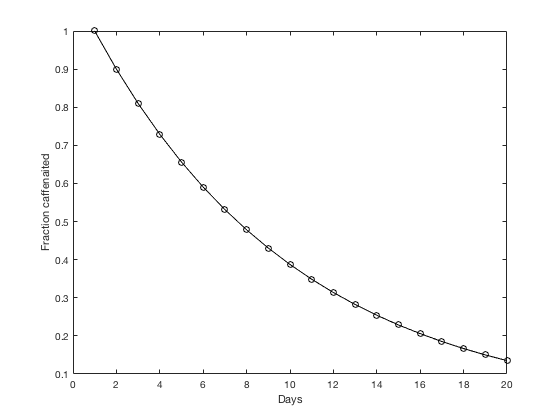

N = 10; % number of scoops in each jar
nMax = 2*N; % max number of days to simulate
x = ones(1,nMax); % fraction caffenaited
x(1) = 1.0; % initial fraction caffenaited

for n=2:nMax
    
    x(n) = (1-1/N)*x(n-1);
    
end % finished loop through days

figure;
plot(x,'-ok');
ylabel('Fraction caffenaited');
xlabel('Days');

 - Sometimes simulation gives unexpected results, i.e., our brains are not always good simulators.

 - Models have assumptions that are wrong.

# 1. Functions of a continuous variable

## 1.1 Functions

Let u(t) be the fluorescence signal from a microscope at time t, with t in seconds:

- u(t) = A sin(omega t).

- Functions are black boxes you feed an input and get an output.

- Two ways to define a function: in-line u=@(t)t^2 and in a separate m-file function

%% Define a function in-line
% u=@(t) A*sin(omega*t) + A_0;

u=@(t,A,omega,A_0) A*sin(omega*t) + A_0;
display(u(0.1,1.1,2.6,0.01)); % t=0.1, A=1.1, omega=2.6, A_0=0.01

    0.2928



A     = 1.1; % fluorescence intensity units
omega = 2.6; % rad/s
A_0   = 0.01;
u=@(t) A*sin(omega*t)+A_0;

display(u(0.1));

    0.2928



## a function defined in a separate m-file

There is a file in this directory called uBlackBox.m that defines a function

display(uBlackBox(0.1));

    0.7760



## 1.1.1 Functions versus an array of samples

Function on a continuous set (can't be plotted directly) versus array of samples u(tArray) (which can be plotted)

tArray = linspace(0,1.6,200);
uArray = u(tArray); % an array of samples of u

figure; hold on;
plot(tArray,uArray);
ylabel('u');
xlabel('t');

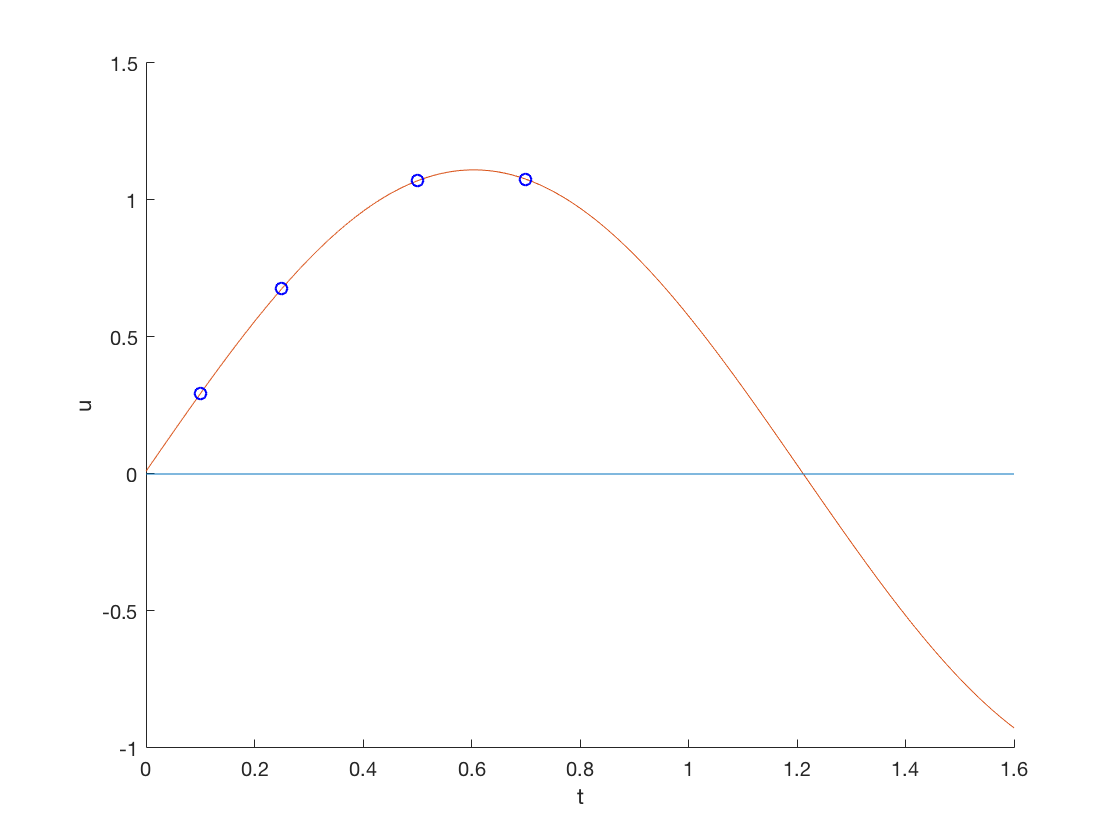

tArrayCoarse = [0.1 0.25 0.5 0.7];
uArrayCoarse = u(tArrayCoarse);

plot(tArray,uArray);
plot(tArrayCoarse, uArrayCoarse, 'ob')
refline(0,0); % add horizontal line at u=0

## 1.1.2 Where is a function zero? Symbolic, graphical, numerical: fzero, numerical from sample

Symbolicaly, we know the function u(t) is zero when $\sin(\omega*t) = - A_0/A$, so $t = 1/\omega*\rm{asin}(-A_0/A)$.

display(1/omega*asin(-A_0/A));

   -0.0035



display(1/omega*(pi-asin(-A_0/A)));

    1.2118



Graphically, we see it is around t=1.2s. 

Numerically, given the function:

tZero = fzero(u,1.2);
display(tZero);

tZero = 1.2118

Numerically, from the sample:

[minimalValue, indexOfMin] = min( (uArray - 0).^2 );
display(tArray(indexOfMin));

    1.2141

